# ** IO3xx BiSS Loopback**

This example shows how to perform a loopback test using IO3xx BiSS. You can test the basic IO3xx BiSS functionality by running this example.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one I/O module from the IO3xx family installed

- Speedgoat configuration file that supports 1**x BiSS Master and 1x BiSS Slave**

- Connector cable from the I/O module to the terminal board

- Terminal board with jumper wires

### Test Setup

In this example, BiSS Master channel 1 is connected to BiSS Slave channel 1. You must therefore connect the pins on the terminal board where these channels are located. The exact pins depend on the configuration file used.

In the pin mapping of your configuration file, locate the functionalities specified in the table below and then locate the corresponding pins on the terminal board. Connect these pins with jumper wires. 

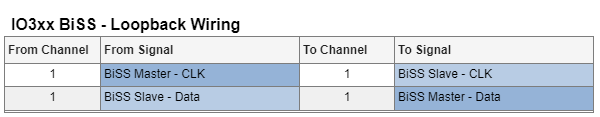

## Initialize and Open the Simulink model

 
% Open Simulink model
modelName = 'sgMdl_IO3xx_BiSS_Loopback';
open_system(modelName);

Before the Simulink model can be built, the I/O module and configuration file must be specified in the IO3xx Setup block, as this example can be executed on different configurable I/O modules. First, open the mask of the IO3xx Setup block and select your I/O module from the drop-down. Once the mask has extended, select the configuration file that supports the required functionalities.

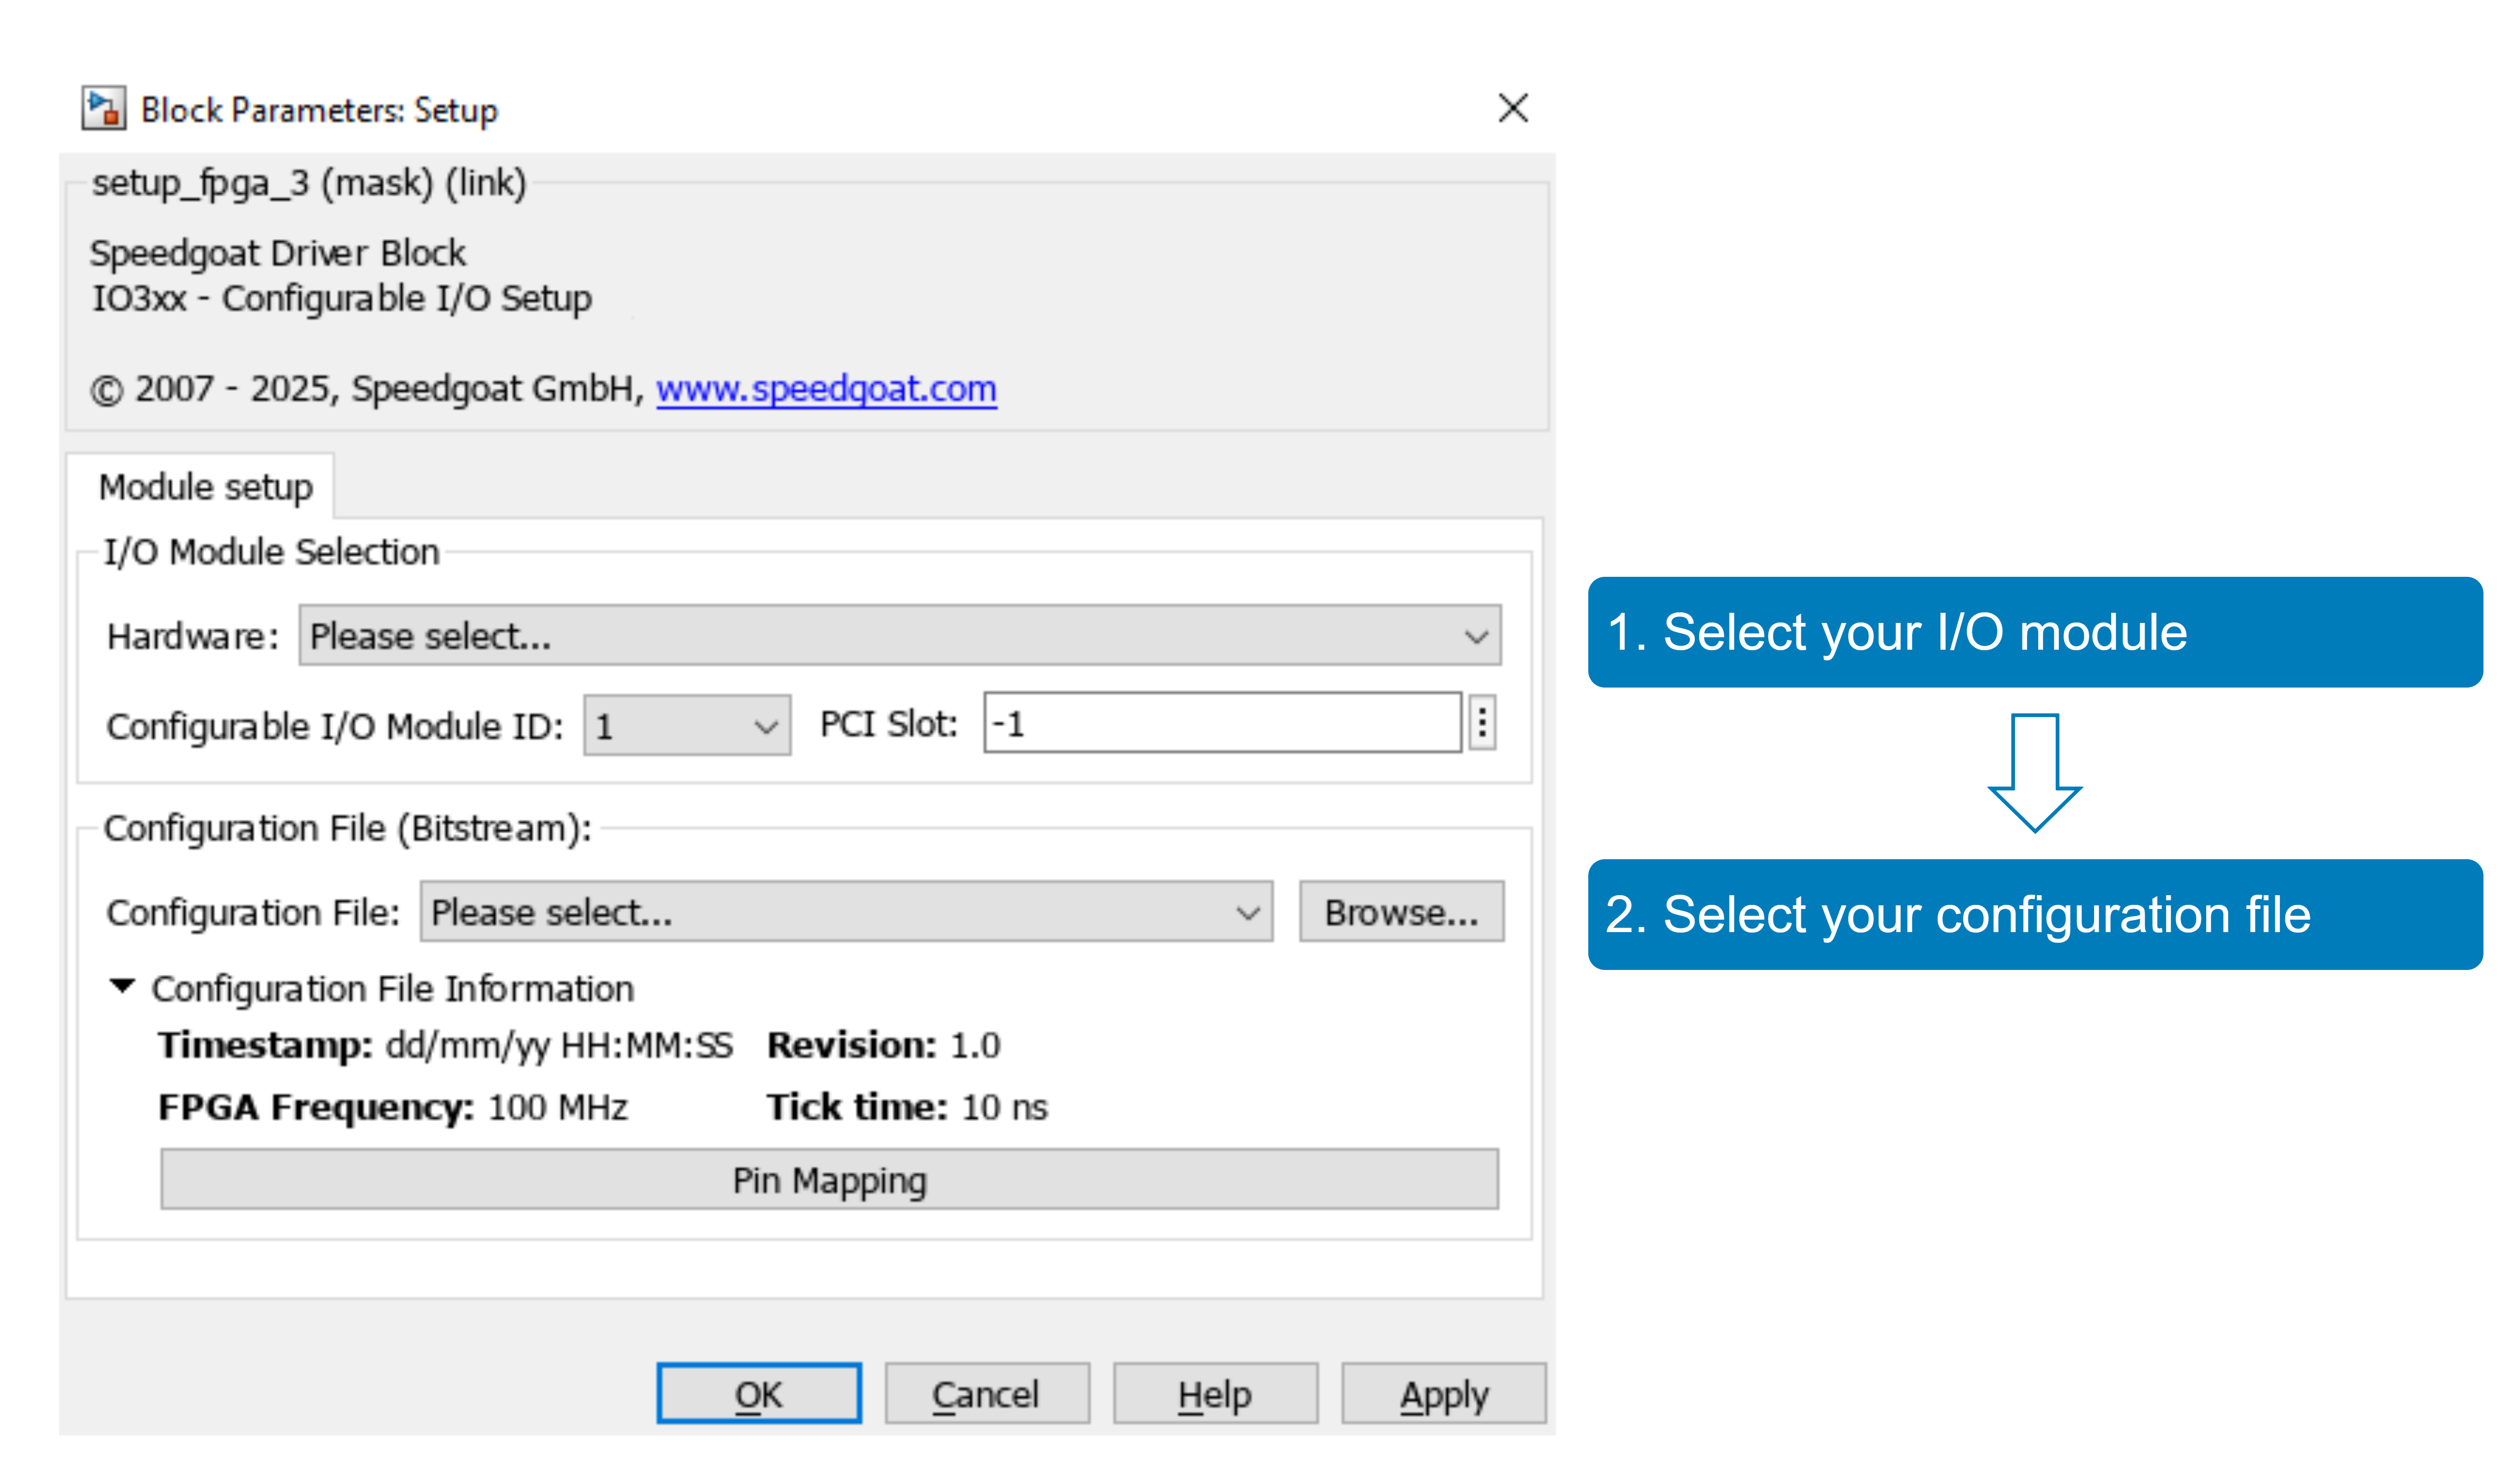

With the **Pin Mapping** button you can now check where the functionalities are located.

### Model Description

In this model, BiSS master channel 1 transmits 32 bits of data, an 8-bit CRC value, a warning message and an error bit, and BiSS slave channel 1 receives these items. The scope displays the data (RxData), CRC, warning message and error bit received and indicates any transmission errors. 

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model:

 
% Build the Simulink model
slbuild(modelName);         % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;            
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName); 
tg.setStopTime(10);

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName,'SimulationMode','external')    % put model into External Mode
set_param(modelName,'SimulationCommand','connect')  % connect with External Mode  

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;

### Check the Results

To check the loopback is working as expected, open the Simulink scope that is connected to the Serial Read block. *The scope must display the Rx Data, the CRC-Data, the warning- and error-data as follows*. Also, the Transmission Error must be low:

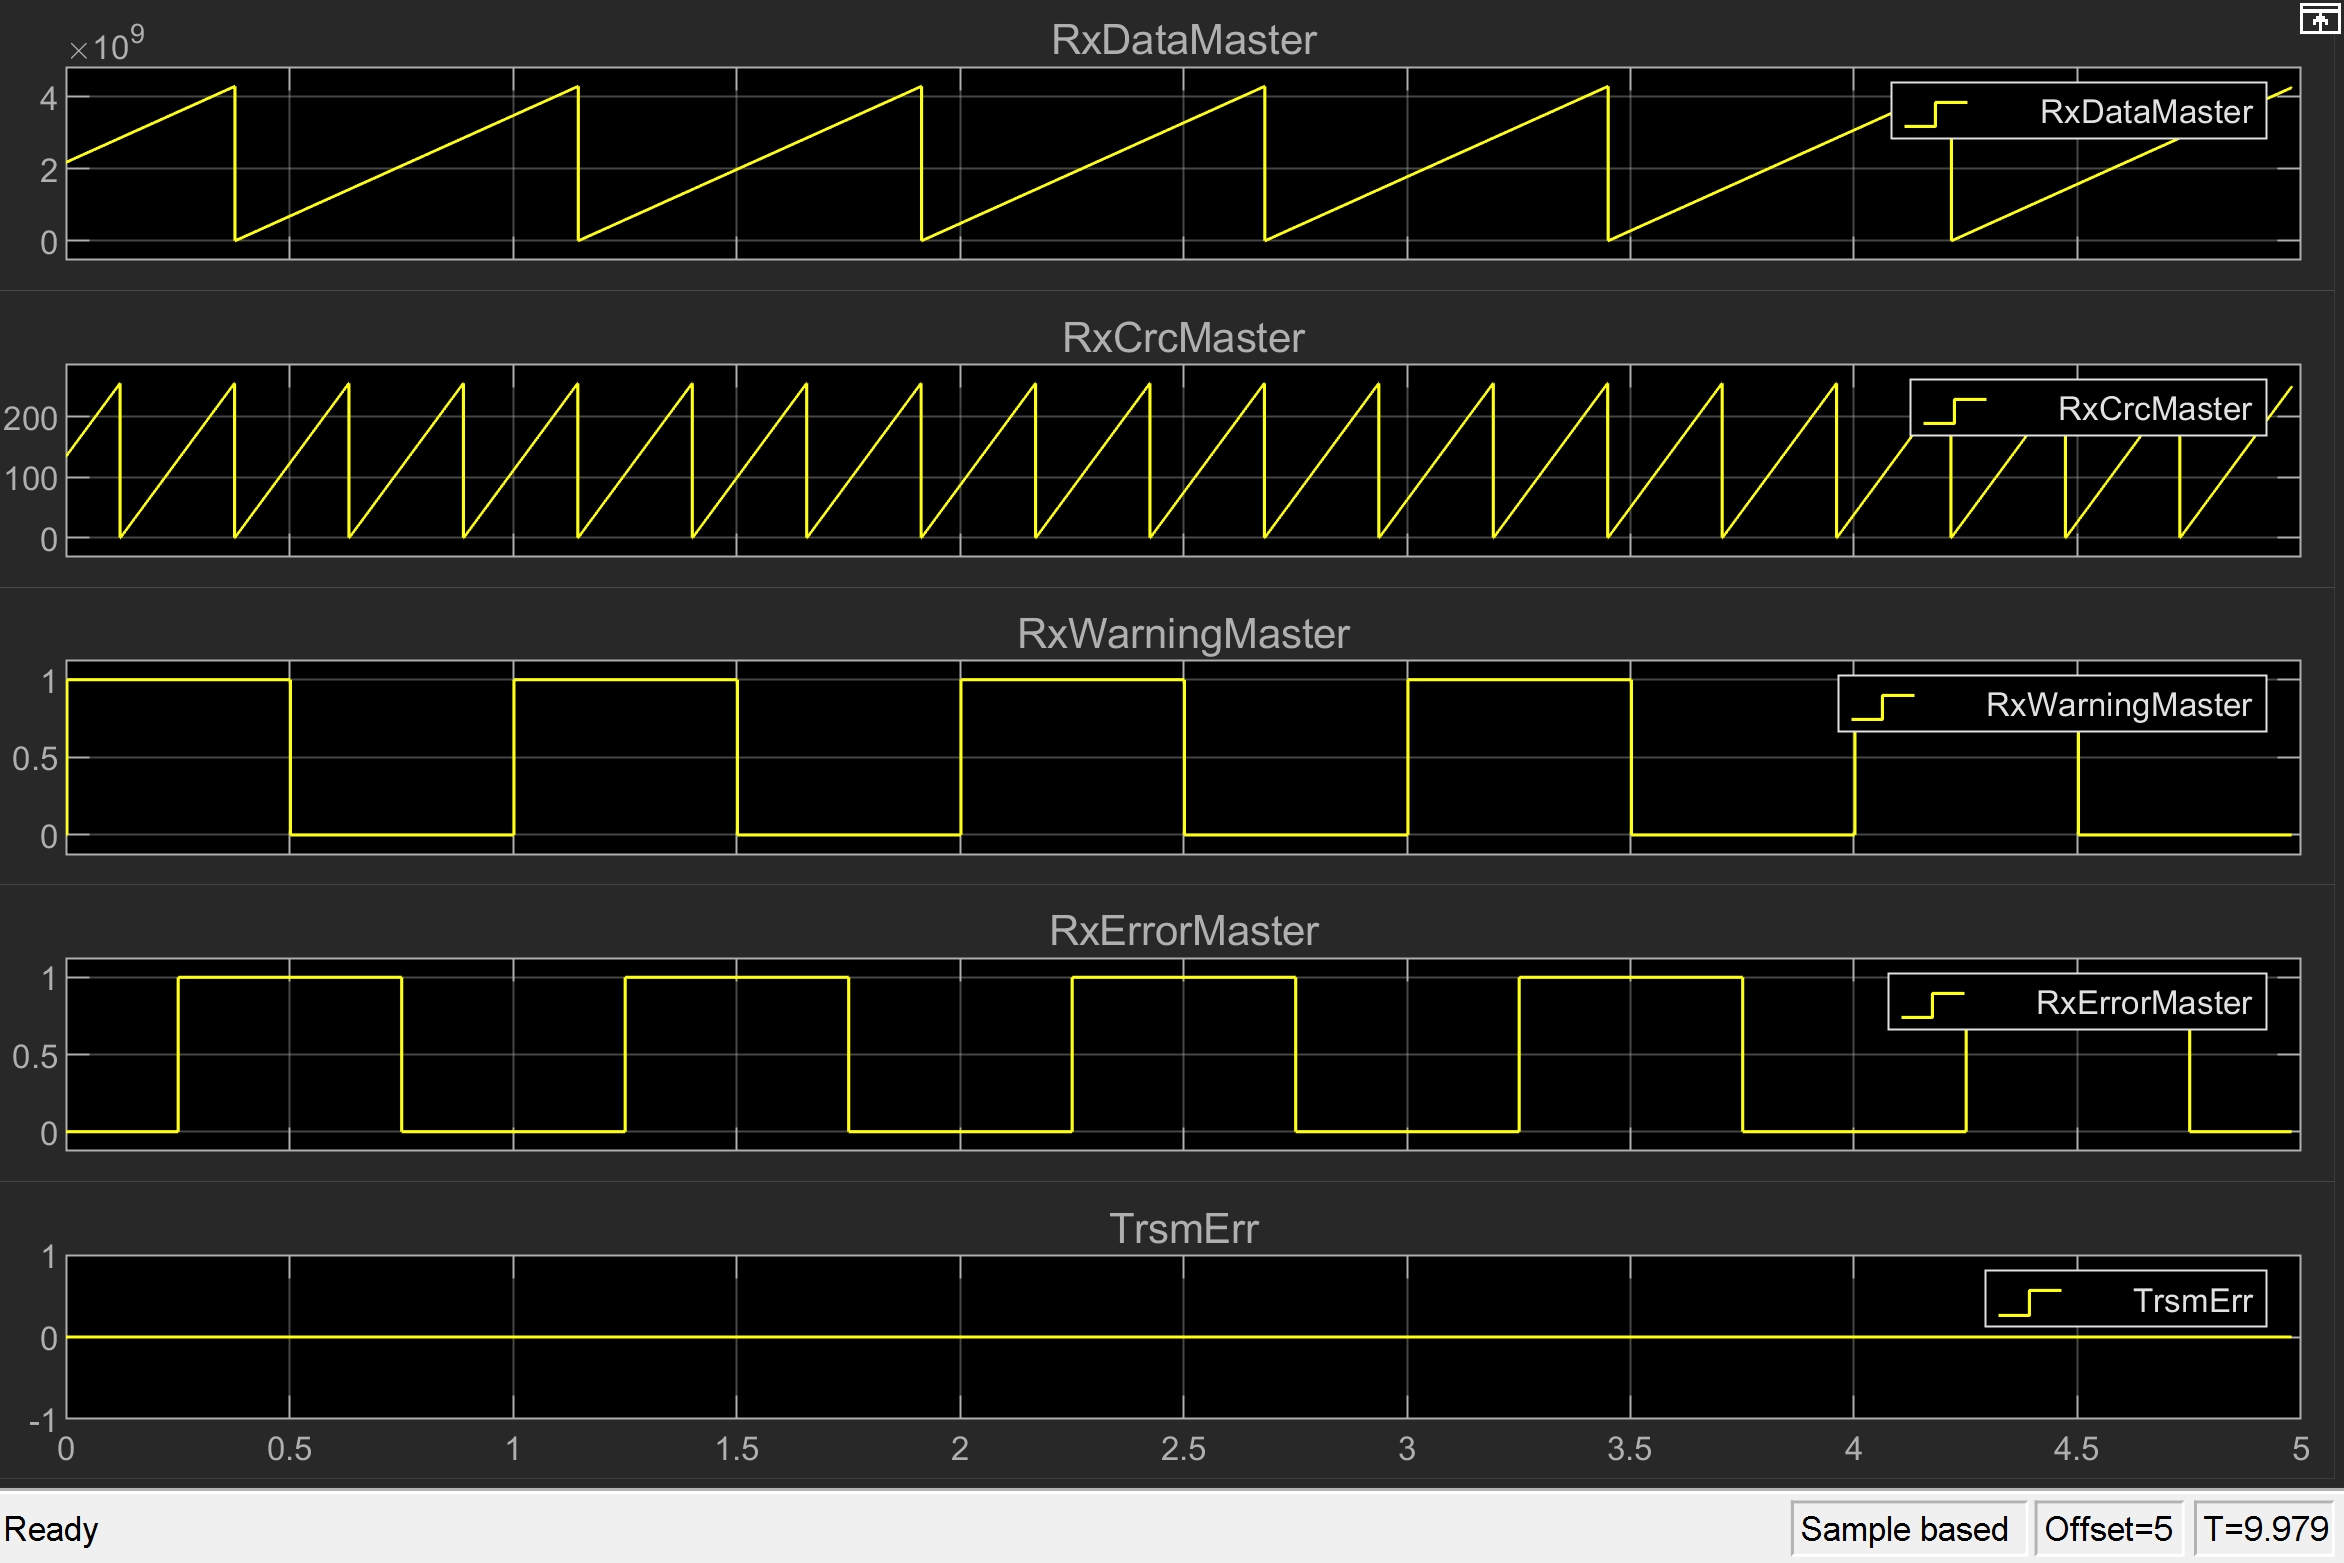

## Additional References

- [IO3xx BiSS documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_biss)

- [IO3xx BiSS Usage Notes](https://www.speedgoat.com/help/slrt/page/io_main/refentry_biss_usage_notes) 